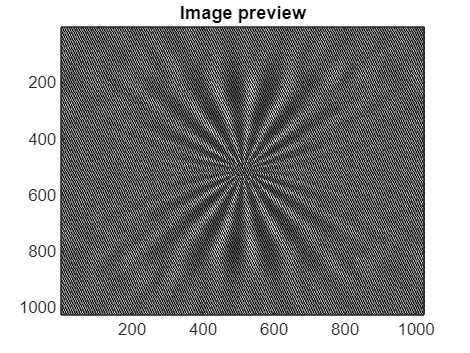

% test load file and phase rec.m
file = 'Star_0_Thick_250.bmp';
im = imread(file);
figure(8), imagesc(im), colormap gray, title 'Image preview'

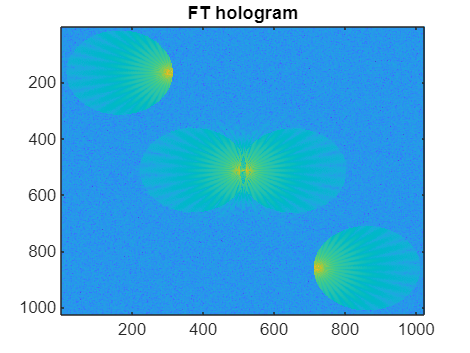

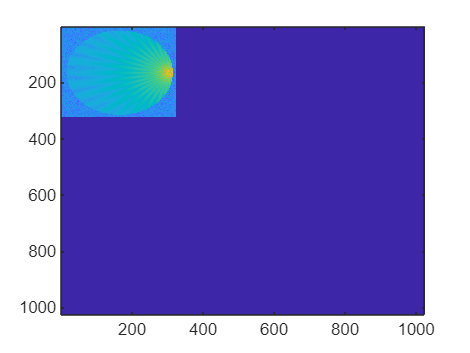

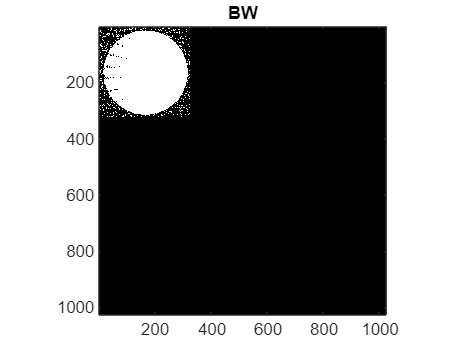

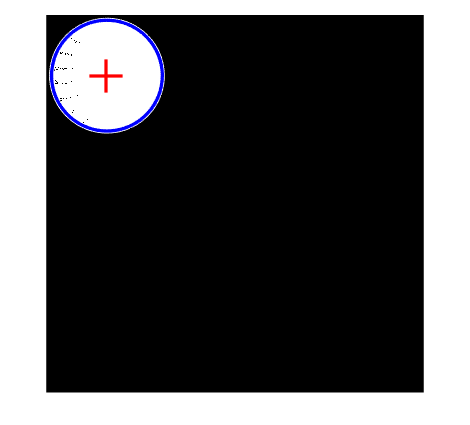

Centro detectado: (165.10, 164.98)
Radio detectado: 150.19 píxeles


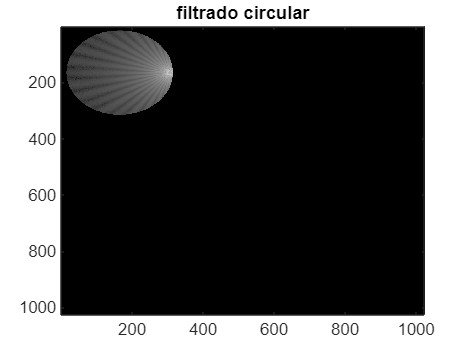

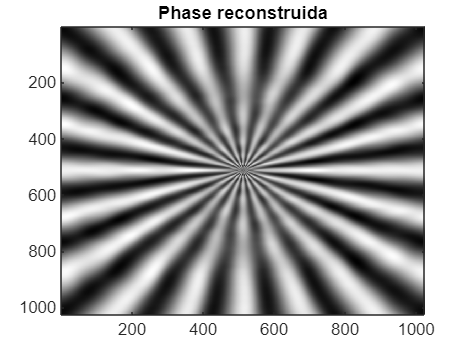

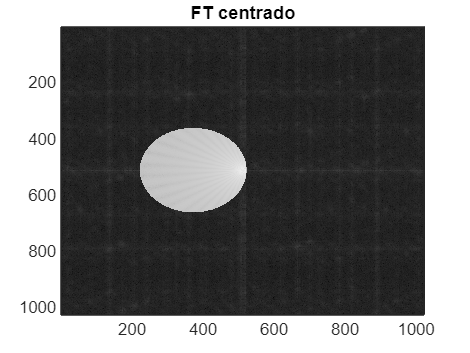


% params stolen from og file
% Define dx and dy (pixel pitch in um)
dx = 4.65; 
dy = 4.65;
% Define wavelength 
lambda = 0.532;
% Define the Cartessian region for the spatial filter 
region = 2;

complexFeild  = Ophase_rec(file, dx,dy,lambda,region);

[N,M] = size(complexFeild);

N = 1024

M = 1024

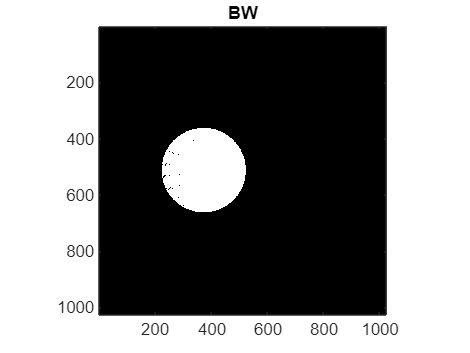

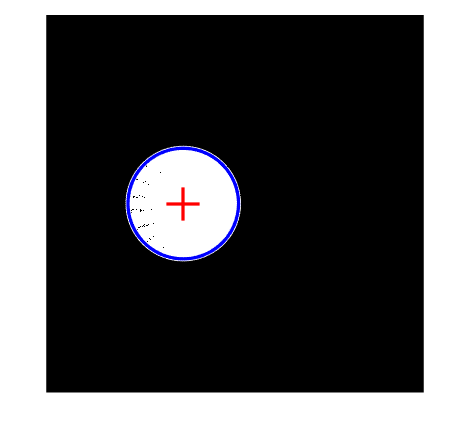

Centro detectado: (372.14, 512.05)
Radio detectado: 149.95 píxeles



zero_Phase = phaseNorm(complexFeild);
phaseDeg = angle(zero_Phase);

ns = 1.52; % borosilicato
nim = 1; % air
thickness = (phaseDeg * lambda)/ (2* pi * (ns-nim));
[filter, circ] = circular_filter(complexFeild,zero_Phase,12);